## **1. Consider an 11th -order analog Butterworth lowpass filter 𝐻𝐶(𝑠) with 3 dB cutoff frequency of 15 Hz.**

n = 11;
fc = 15;
fs = 1000;

**a. Determine and graph the pole locations of 𝐻𝐶(𝑠).**

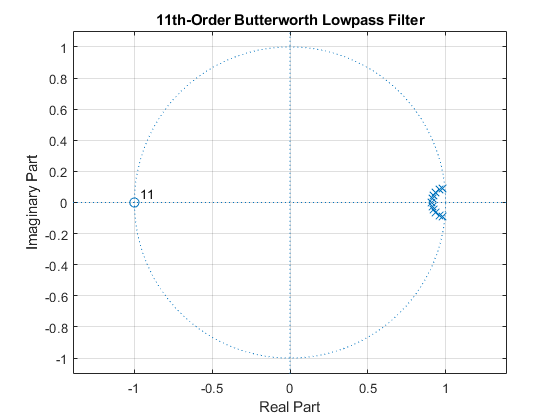

[z,p,k] = butter(n,fc/(fs/2));
figure(1);
zplane(z,p)
grid
title('11th-Order Butterworth Lowpass Filter')

**b. Plot the magnitude and log-magnitude responses over [0, 150] Hz range. **

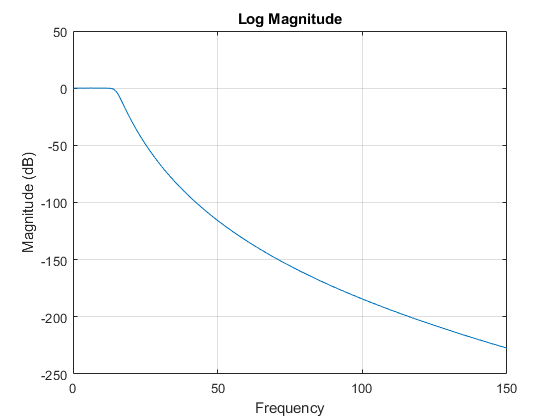

[b,a] = butter(n,fc/(fs/2));
[h,w] = freqz(b,a,[0:1:150],fs);
figure(2);
plot(w,20*log10(abs(h)))
title("Log Magnitude")
ylabel('Magnitude (dB)')
xlabel('Frequency')
grid on;

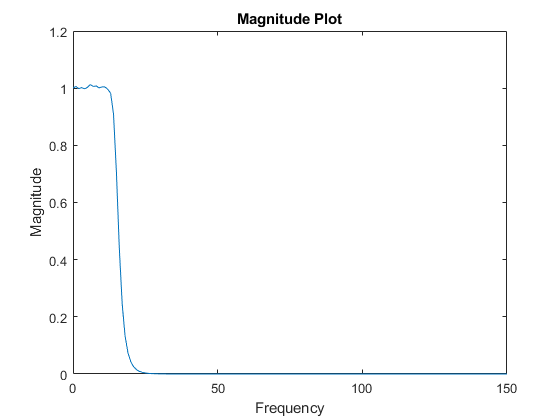

figure(3);
plot(w,abs(h));
ylabel('Magnitude')
xlabel('Frequency')
title('Magnitude Plot')

**c. Determine frequencies at which the attenuation is 20 dB and 50 dB. **

load("q8_1_c.mat")
cursor_info1

cursor_info1 = 1×4 struct array with fields:
    Target
    Position
    DataIndex


From Graph we can see at frequencies are 18Hz and 25Hz respectively